% Pulse Code Modulation
clc
close all
clear all
t = 0:0.0001:20; % Sampling at niquist rate
c=input('Enter Bit Depth Of PCM Coding:');

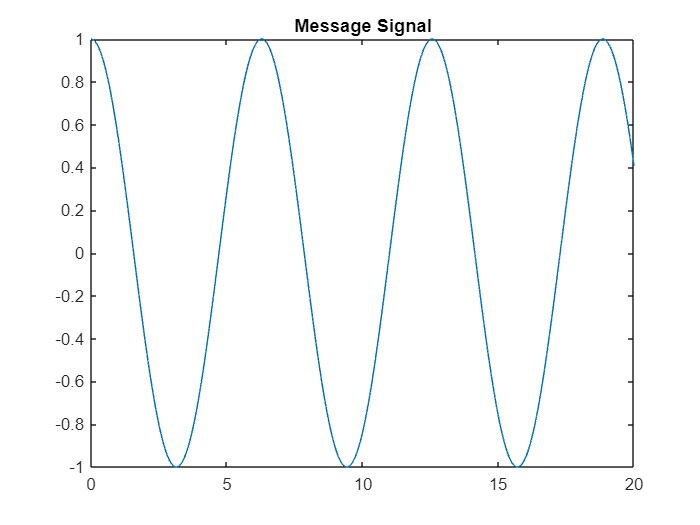

% Message Signal
msg = cos(t);
plot(t,msg);
title('Message Signal');

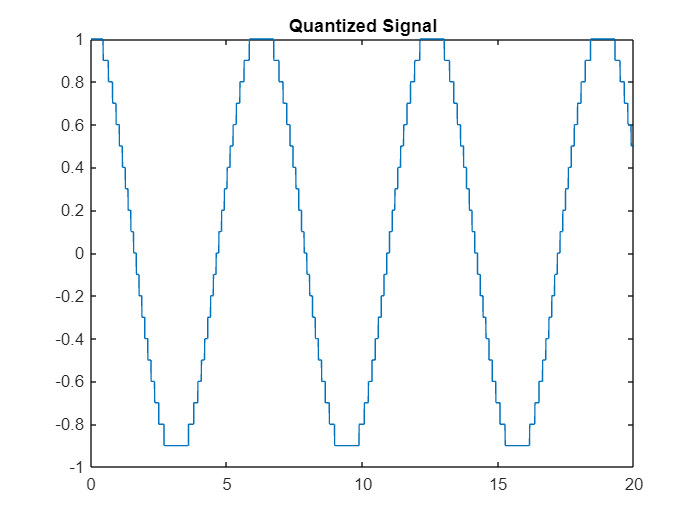

% A quantization partition defines several contiguous, nonoverlapping ranges of 
% values within the set of real numbers.
part = -1:0.1:1; 
% A codebook tells the quantizer which common value to assign to inputs that
% fall into each range of the partition.
codebook = -1:0.1:1.1;

[~,quants] = quantiz(msg,part,codebook);

plot(t,quants);
title('Quantized Signal');

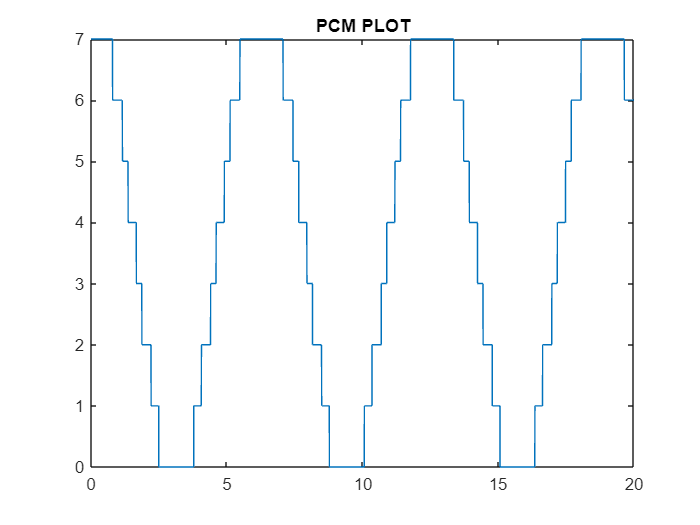

y=uencode(quants,c);
ybinary=dec2bin(y,c); % Converting it to final binary form to make it transmit ready
plot(t,y);
title('PCM PLOT');